% compare different correlation source

clearvars; close('all');


% GNSS headng
% load("data\CS_GNSS.mat");
load("data\RT_GNSS.mat");
WatStructG=WatStruct;NavStructG=NavStruct;SensStructG=SensStruct;
% sig compasss
% load("data\CS_SIG.mat"); region='Celtic Sea';
load("data\RT_SIG.mat"); region='Rockall Trough';
WatStructS=WatStruct;NavStructS=NavStruct;SensStructS=SensStruct;



for mm = 1:numel(WatStructS)

    figure;
    t = tiledlayout(3,1);
    

####     Plot GNSS BEARING AND HEADING


    nexttile
    x=NavStructG(mm).timestamp;
    y=NavStructG(mm).gpsBearing;
    y(y>360)=nan;y(y<0)=nan;
    
    p1=plot(x,y,'b-',...
        'MarkerSize',2);
    hold on
    
    x=NavStructS(mm).timestamp;
    y=NavStructS(mm).gpsHeading;
    y(y>360)=nan;y(y<0)=nan;
    
    p2=plot(x,y,'k-',...
        'MarkerSize',2);
    
    
    x=NavStructS(mm).timestamp;
    y=SensStructS(mm).heading_deg;
    y(y>360)=nan;y(y<0)=nan;
    
    p3=plot(x,y,'m-',...
        'MarkerSize',2);
    
    datetick('x','keeplimits');
    xlabel('Time')
    ylabel('Degrees')
    
    legend('GNSS bearing','GNSS heading','ADCP heading','Location','bestoutside')
    
    

####     Plot current magnitude

    nexttile;
    x=NavStructG(mm).timestamp;
    y=movmean(WatStructG(mm).vMag_ms(1,:),10);
    
    p1=plot(x,y,'r-',...
        'MarkerSize',2);
    hold on
    
    x=NavStructS(mm).timestamp;
    y=movmean(WatStructS(mm).vMag_ms(1,:),10);
    p2=plot(x,y,'k-',...
        'MarkerSize',2);
    
    datetick('x','keeplimits');
    xlabel('Time')
    ylabel('Bin 1 velocity m s^{-1}')
    legend('GNSS','ADCP','Location','bestoutside');

####     Plot current DIRECTION

    
    nexttile;
    x=NavStructG(mm).timestamp;
    y=movmean(WatStructG(mm).vDir(1,:),10);
    
    p1=plot(x,y,'r-',...
        'MarkerSize',2);
    hold on
    
    x=NavStructS(mm).timestamp;
    y=movmean(WatStructS(mm).vDir(1,:),10);
    p2=plot(x,y,'k-',...
        'MarkerSize',2);
    
    datetick('x','keeplimits');
    xlabel('Time')
    ylabel('Bin 1 current direction')
    legend('GNSS','ADCP','Location','bestoutside');
    
    sgtitle([region ' shelf break ' num2str(mm)]) ;
    print(gcf,'-dpng',['figures/' region '_correction_check_' num2str(mm)])
    

### Plot currents

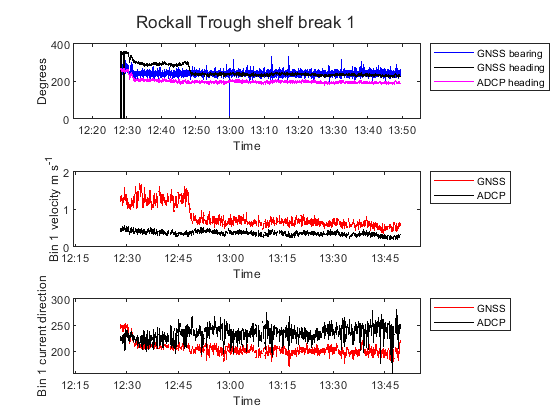

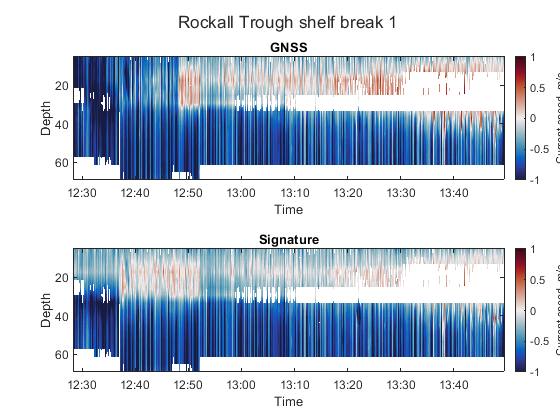

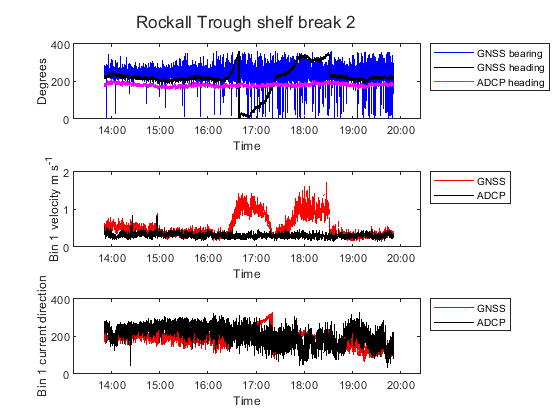

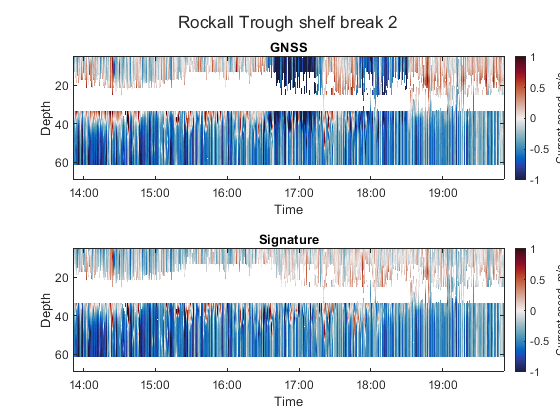

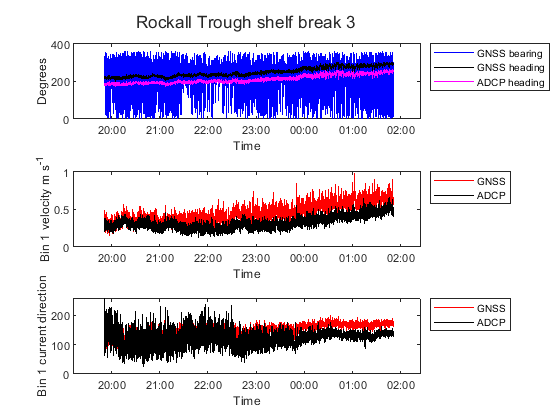

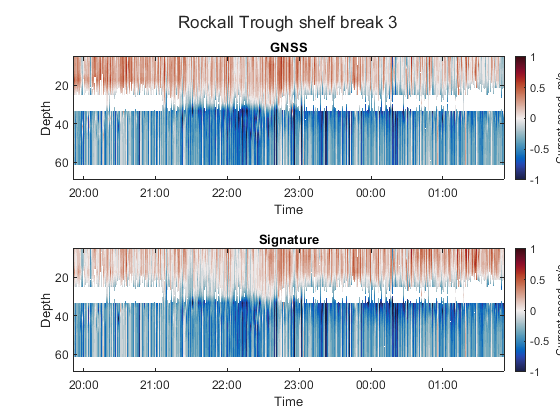

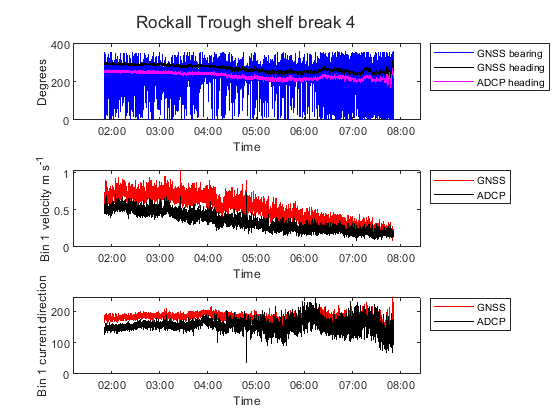

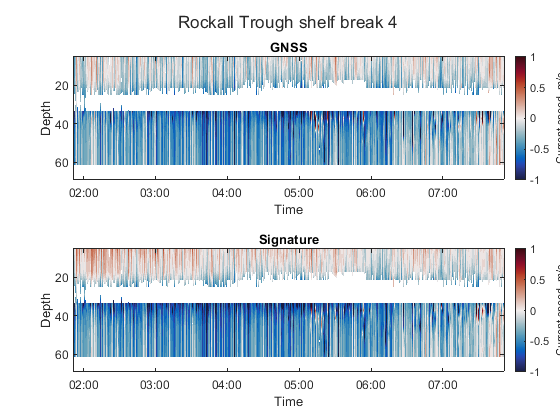

    figure;
    t = tiledlayout(2,1);
    nexttile;
    x=NavStructG(mm).timestamp;
    y=WatStructG(mm).binDepth(:,1);
    z=WatStructG(mm).vEast_ms;
    
    contourf(x,y,z,100,'LineColor','none');
    caxis([-1 1]);
    cmocean('Balance','Pivot',0);
    C=colorbar;
    axis ij
    datetick('x','keeplimits');
    xlabel('Time');
    ylabel('Depth');
    ylabel(C,'Current speed, m/s');
    title('GNSS')

    nexttile;
    x=NavStructS(mm).timestamp;
    y=WatStructS(mm).binDepth(:,1);
    z=WatStructS(mm).vEast_ms;
    
    contourf(x,y,z,100,'LineColor','none');
    caxis([-1 1]);
    cmocean('Balance','Pivot',0);
    C=colorbar;
    axis ij
    datetick('x','keeplimits');
    xlabel('Time');
    ylabel('Depth');
    ylabel(C,'Current speed, m/s');   
    title('Signature')
    sgtitle([region ' shelf break ' num2str(mm)]) ;
    
    print(gcf,'-dpng',['figures/' region '_vvel_' num2str(mm)])
end